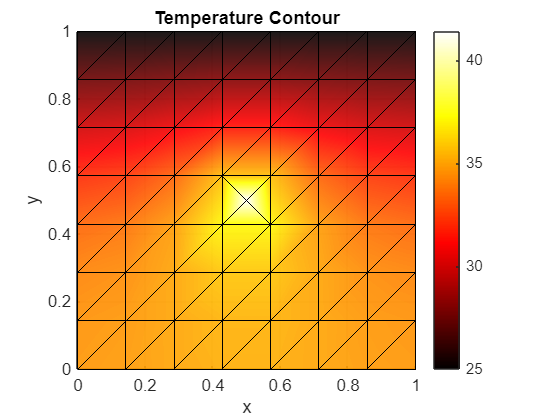

clc; clear;

%% Parameters
T0 = 25;                    % Dirichlet or ambient temperature
k = 50;                     % Thermal conductivity
q_mag = 1000;               % Point source magnitude
nx = 7; ny = 7;             % Mesh density

%% Mesh Generation

Lx = 1; Ly = 1;
dx = Lx / nx; dy = Ly / ny;
[x, y] = meshgrid(0:dx:Lx, 0:dy:Ly);
nodes = [x(:), y(:)];
numNodesX = nx + 1;

elements = [];
n5 = -1; % to track center node index
for j = 1:ny
    for i = 1:nx
        n1 = (j - 1) * numNodesX + i;
        n2 = n1 + 1;
        n3 = n1 + numNodesX;
        n4 = n3 + 1;

        if i==4 && j==4
            
            % Add center node only once
            center_coord = mean(nodes([n1, n2, n4, n3], :), 1);
            nodes = [nodes; center_coord];
            n5 = size(nodes, 1);  % Save index

            elements = [elements;
                n1, n2, n5;
                n2, n4, n5;
                n4, n3, n5;
                n3, n1, n5];
               centre = [n3, n1, n5]; 
        else
            elements = [elements;
                n1, n2, n4;
                n1, n4, n3];
        end
    end
end

%% FEM Assembly
N = size(nodes, 1);
K = zeros(N);
F = zeros(N, 1);


for e = 1:size(elements, 1)
    node_ids = elements(e,:);
    coords = nodes(node_ids, :);

    Q = [1, 0, -1; 0, 1, -1];
    J = Q * coords;
    Ae = 0.5 * abs(det(J));
    ke = k * Ae * Q' * inv(J) * inv(J') * Q;
    K(node_ids, node_ids) = K(node_ids, node_ids) + ke;

    if node_ids == centre
             Fe = q_mag * [0; 0; 1];
             F(node_ids) = Fe;
    end
end

%% Apply Boundary Conditions
K_mod = K; F_mod = F;
top_nodes = find(abs(nodes(:,2) - 1) == 0);

for n = top_nodes'
    K_mod(n,:) = 0;
    K_mod(n,n) = 1;
    F_mod(n) = T0;
end

%% Solve System
T = K_mod \ F_mod;

%% Plot Results
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, ...
    'EdgeColor', 'k', 'FaceColor', 'interp', 'FaceAlpha', 0.9);
view(2); axis equal tight; colorbar;
xlabel('x'); ylabel('y'); title('Temperature Contour');
colormap('hot');

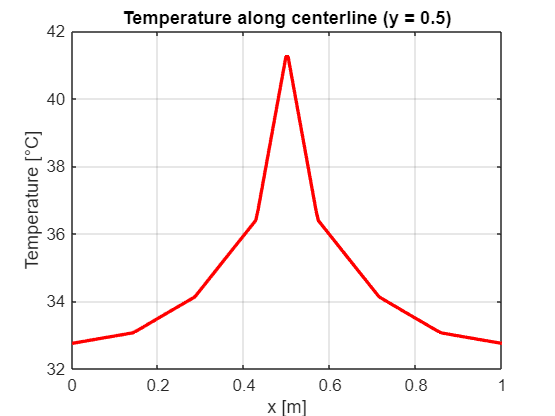


% Plot centerline profile
x_vals = linspace(0, 1, 200);
y_vals = 0.5 * ones(size(x_vals));
T_mid = griddata(nodes(:,1), nodes(:,2), T, x_vals, y_vals, 'linear');

figure;
plot(x_vals, T_mid, 'r-', 'LineWidth', 2);
xlabel('x [m]'); ylabel('Temperature [°C]');
title('Temperature along centerline (y = 0.5)');
grid on;